# Systems of Ordinary Differential Equations

Numerical solvers like `ode45` solver in MATLAB expect your system (or model) to be expressed as a first-order system. This document provides a brief overview of how to convert higher-order ordinary differential equations (ODEs) into a system of first-order ODEs, which can then be solved using numerical methods like `ode45`.

The key to solving these types of problems is to set up the model expressions independent of the numerical (software) implementation.  They key steps in the set up are...

- **explicilty formulate a state vector convention** and 

- **express the ODE in vector form**.  

## General Vector Form - System of ODEs

A system of ordinary differential equations can be written in vector form as:


$$\frac{d\mathbf{x}}{dt} = \mathbf{f}(t, \mathbf{x}(t))
$$


where

- $\mathbf{x}(t) \in \mathbb{R}^n$ is the vector of *state variables*

- $t$ is the independent variable - often time

- $\mathbf{f}: \mathbb{R} \times \mathbb{R}^n \to \mathbb{R}^n$ is a vector-valued function defining the *dynamics.*

Note that the first derivative of each *state variable is expressed in terms of only the state variables themselves and time*. This is a key feature of systems of ODEs, allowing for the representation of complex dynamics in a structured manner.  

## N-th order ODE as N first-order ODEs

Any N-th order ODE can  be reformulated as a system of N first-order ODEs. This approach is fundamental in mathematical modeling and numerical methods, as it allows higher-order equations to be solved using methods that are designed for systems of first-order equations, like MATLAB’s `ode45`.

Consider the genearl n-th order ODE 

$    y^{(n)} = f(t, y, y', \dots, y^{(n-1)})
$    (1)

### Define the State Variables

The *state* variables are not unique, but a conventional choise is to define a new set of state values $x_i$ for $i = 1, 2, \ldots, n-1$.   We define $x_1 = y , \,\,
x_2 = dy/dt$ up to $x_n = y^{(n-1)}$.

### Define the State Vector

Now express the original equation in terms of these state variables, yielding a system of first-order ODEs:


$$\frac{d \mathbf{x}(t)}{dt} =        
\begin{cases}
            \dot{x}_1 = x_2, \\
            \dot{x}_2 = x_3, \\
            \vdots \\
            \dot{x}_{n-1} = x_n, \\
            \dot{x}_n = f(t, x_1, x_2, \dots, x_n).
        \end{cases}$$


This converts the single n-th order ODE into a system of n first-order ODEs, which can then be solved with methods such as ode45.

This transformation is universally applicable because it leverages the fundamental property that *any n-th order derivative can be expressed as a sequence of first-order derivatives*, allowing the problem to be represented in* state-space form*.

## Example: Mass-Spring-Damper System, AKA Damped Harmonic Oscillator

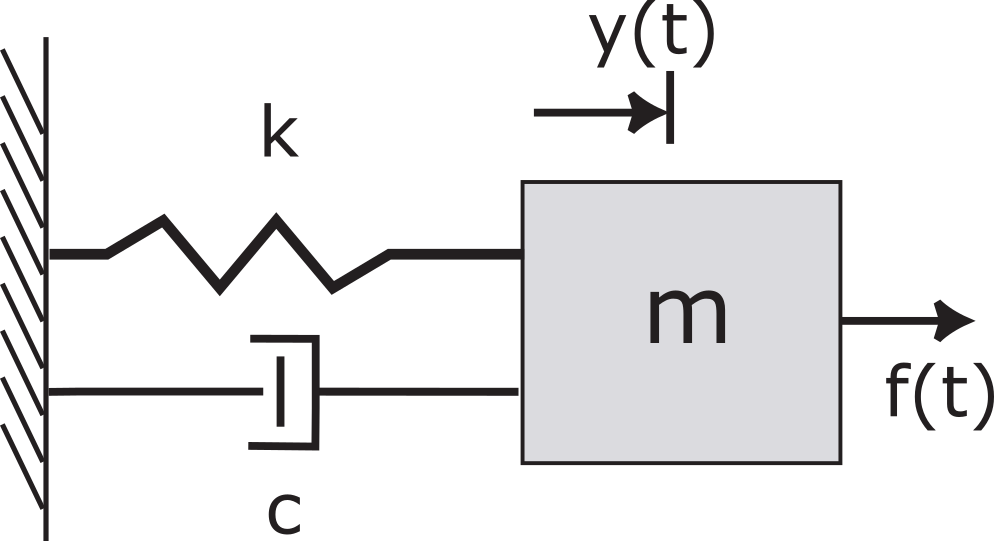

Consider the second-order ODE of a damped harmonic oscillator model:


$$m\, \ddot{y}(t) + c \, \dot{y}(t) + k\, y(t) = 0
$$


with initial conditions


$$y(t=0) =  1.0 \: \text{m}\\
\dot{y}(t=0) = 0 \: \text{m/s}$$


where

- $y(t)$ is the displacement 

- $m$ is the mass,

- $c$ is the damping coefficient, and

- $k $ is the spring constant.

### Define the State Variables

To convert this into a system of first-order ODEs, we define two new state variables:


$$x_1 (t) = y(t) \quad \text{(position) 
$$



$$x_2(t)  =  \dot{y}(t) \quad \text{(velocity)}.$$


### Define a State Vector

It is important to explicity define the convention you will use for the order in the state vector, $\mathbf{x}(t)$. There is not a unique order to use in the state vector (no right or wrong order to use), but you will* need to be consistent* when implementing the problem in software, so it is important to write down your intentions.

We will choose this order:


$$\mathbf{x}(t) =
\left\{ \begin{array}{c}
y(t) \\ \dot{y}(t)
\end{array} \right\}
=
\left\{ \begin{array}{c}
x_1(t) \\ x_2(t)
\end{array} \right\}.$$


(We could equivalently choose the opposite order:


$$\mathbf{x}(t) =
\left\{ \begin{array}{c}
\dot{y}(t) \\ {y}(t)
\end{array} \right\}
=
\left\{ \begin{array}{c}
x_2(t) \\ x_1(t)
\end{array} \right\}.$$


We just need to be consistent with either convention!)

### Write the N-th order of ODE as a system of N first-order ODEs

We can the write the system of equations using our state vector definition.


$$\mathbf{\dot{x}}(t) =
\left\{ \begin{array}{c}
\dot{x}_1(t) \\ \dot{x}_2(t)
\end{array} \right\}
=
\left\{ \begin{array}{c}
\dot{y}(t) \\ \ddot{y}(t)
\end{array} \right\}
= 
\left\{ \begin{array}{c}
{x_2}(t) \\ 
-\frac{c}{m}\,x_2(t) - \frac{k}{m} \, x_1(t)
\end{array} \right\}$$


This system is now ready for solving with MATLAB’s `ode45`.

### MATLAB Implementation.

It is important to write down the expressions above, particularly the state vector and the system of ODEs, to make explicit our definition of the problem which we will pass to MATLAB's solver.

Define a rate function, with an interface compliant with the `odexx` solvers.

function dxdt = msd(t, x)
    % Physical parameters of the model
    m = 1;       % kg
    c = 0.2;     % N/(m/s)
    k = 5;       % N/m
    % Unpack the state vector - based on our non-unique definition!
    x1 = x(1);   % Position [m]
    x2 = x(2);   % Velocity [m/s]

ans =    365     2


    % Calculate the derivatives of each state 
    dx1dt = x2;
    dx2dt = -c/m * x2 - k/m * x1;
    % Pack the state rate vector as the return variable
    dxdt = [dx1dt; dx2dt];
end

To comply with the `ode` solver interface, we also need to define the initial state:


$$\mathbf{x}(t=0) =
\mathbf{x}_0 =
\left\{ \begin{array}{c}
y_0 \\ \dot{y}_0
\end{array} \right\}
=
\left\{ \begin{array}{c}
1.0 \\
0.0
\end{array} \right\}.$$


xx0 = [1; 0];

We alo need a time space for the solution, which is context-dependent:

tspan = [0 30];

Now that we have the setup in order, we can call the solver:

[tt, xx] = ode45(@msd, tspan, xx0);

### Interpreting the results

Our non-unique state definition is again key to understanding the format of the results provided by MATLAB.  Example the *shape of our solution matrix*:

size(xx)

We can "unpack" the time-series for each state elements:

position = xx(:,1);
velocity = xx(:,2);

We can then visualize the solution

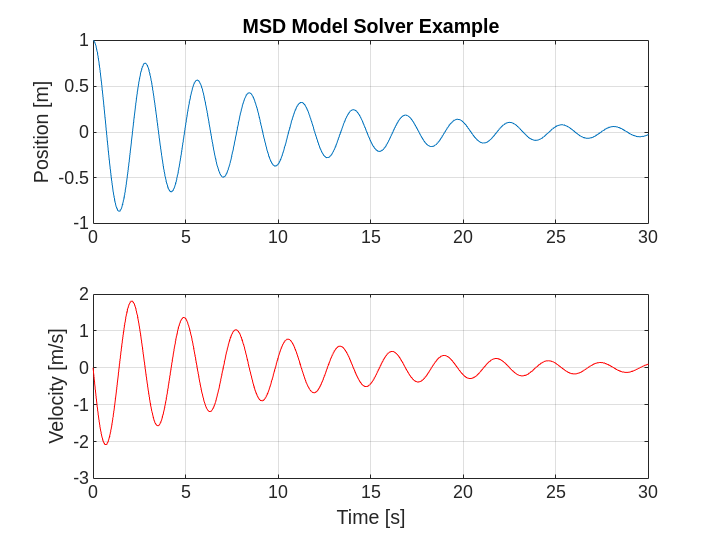

figure(1);
clf();
subplot(2,1,1)
plot(tt, position)
grid("on")

ylabel("Position [m]")
title("MSD Model Solver Example")

subplot(2,1,2)
plot(tt, velocity, 'r')
ylabel("Velocity [m/s]")
grid("on")
xlabel("Time [s]")

##  Summary

- For N-th order ODEs, we can express the problem as a system of N first-order ODEs.

- Creating the *state vector *is a key step to formulating the problem so that we can apply a numerical solver.

- Explicitly writing the expression for the state vector convention and for the system of ODEs is key to setting up the problem and helpful in debugging the implementation.